## Option C - Compare edge detector

Original and noisy Image

clear; clf; clc;
I = imread('cameraman.tif');
rng(42);
In = imnoise(I,'gaussian',0,0.01);

## Sobel and Canny

Like in the Lecture slides I smooth each images before I apply Sobel. Canny includes smoothing.

Is = imgaussfilt(I,1);
Ins = imgaussfilt(In,1);
S = edge(Is,'sobel');
Sn = edge(Ins,'sobel');

C1 = edge(I,'canny',[],1);
C1n = edge(In,'canny',[],1);
C3 = edge(I,'canny',[],3);
C3n = edge(In,'canny',[],3);

## Six edge maps

Every single white pixel is a edge detected.

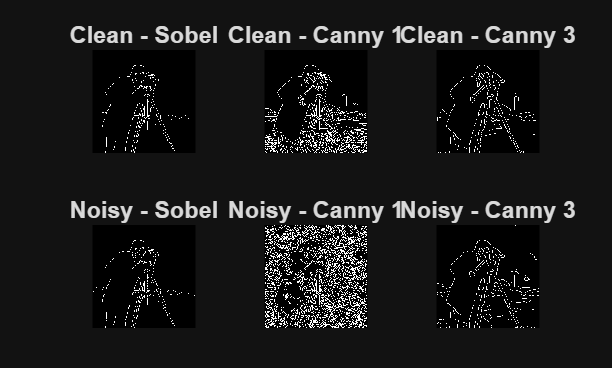

figure;
subplot(2,3,1); imshow(S);   title('Clean - Sobel');
subplot(2,3,2); imshow(C1);  title('Clean - Canny 1');
subplot(2,3,3); imshow(C3);  title('Clean - Canny 3');
subplot(2,3,4); imshow(Sn);  title('Noisy - Sobel');
subplot(2,3,5); imshow(C1n); title('Noisy - Canny 1');
subplot(2,3,6); imshow(C3n); title('Noisy - Canny 3');

if ~isfolder('results')
    mkdir('results');
end

## Number of edge pixels

nnz counts the white pixels in each edge map.

Method = ["Sobel"; "Canny 1"; "Canny 3"];
Clean = [nnz(S); nnz(C1); nnz(C3)];
Noisy = [nnz(Sn); nnz(C1n); nnz(C3n)];
counts = table(Method,Clean,Noisy);
disp(counts)

     Method      Clean    Noisy
    _________    _____    _____

    "Sobel"      2099      2026
    "Canny 1"    7816     18112
    "Canny 3"    2780      3184



## Explain the effect of sigma and of smoothing on false edges in the noisy image

The smoothening reduces changes in the brightness of pixels caused by noise. When we use Canny with th sigma 3 is smoothing the image more than with the sigma 1. With that it detects fewer false edges. But also stronger smoothing can also remove small details.

## Identify one region where an edge is lost or invented

We can see that in the sky there appear white lines and we can see that these are likely false edge.

## Describe one limitation: the edge-pixel count does not measure correctness.

Describe one limitation: the edge-pixel count does not measure correctness.